# Homework 4

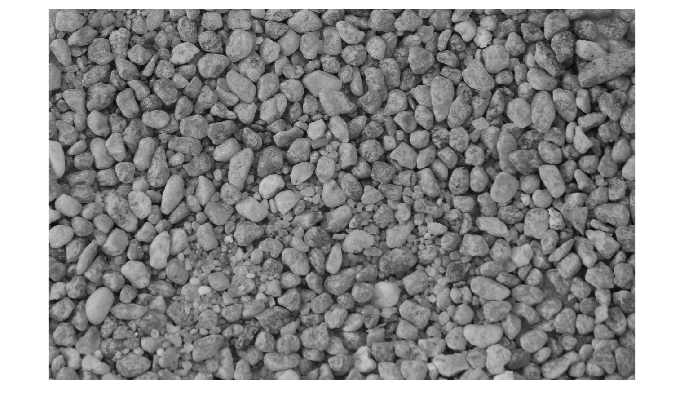

I = rgb2gray(imread("piedra.jpeg"));
imshow(I);

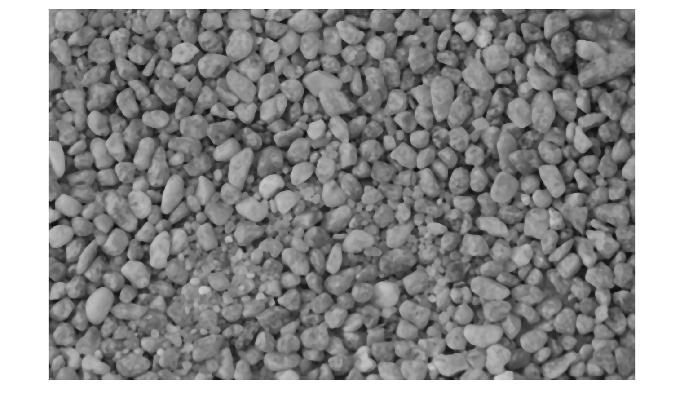


I = medfilt2(I,[7 7]); %filtrat de mediana
imshow(I);

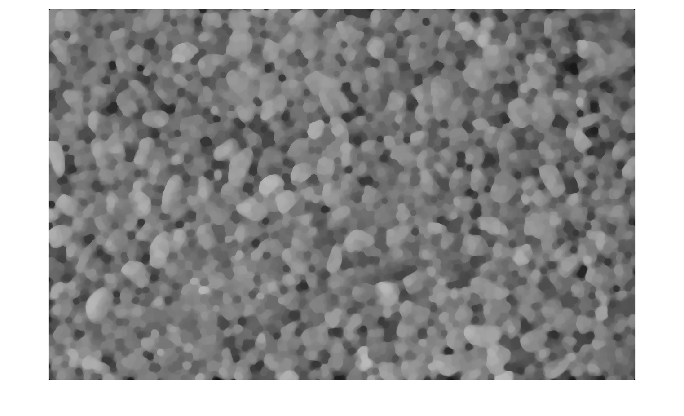


% filtrat morfològic

%SE = ones(7,7);
SE = fspecial("disk",6) > 0;
IFM = imopen(I,SE); % open
IFM = imclose(IFM,SE); % open-close

imshow(IFM);

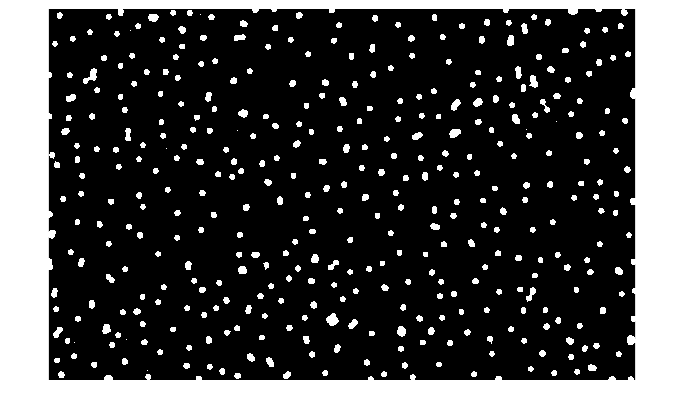



% màxims regionals

IRM = imregionalmax(IFM);

imshow(IRM);

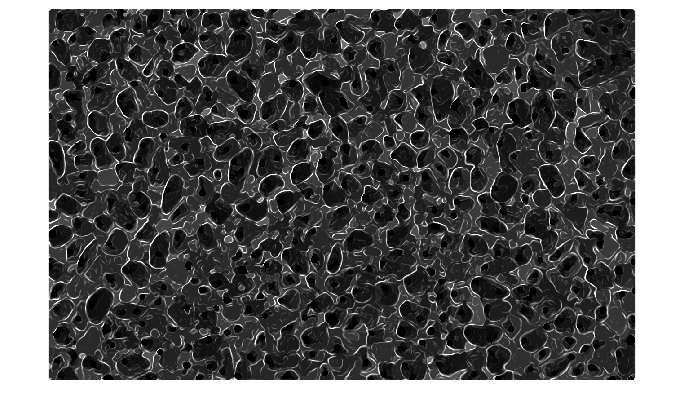


% imatge gradient
Grad = uint8(imgradient(I));

G = imimposemin(Grad, IRM); % Sino en la imatge gradient hi han molts minims locals 
imshow(G,[]);

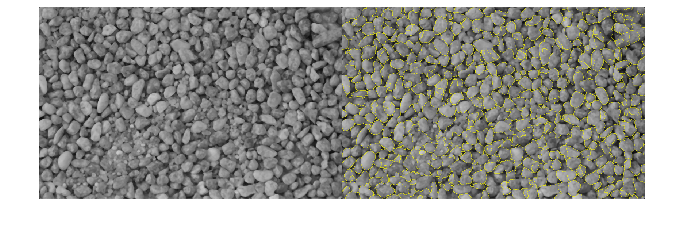


% Watershed
WS = watershed(G);
IB = WS == 0;
RGB = imoverlay(I, IB);
montage({I, RGB})


% Quantitat de pedres = quantitat de components connexes
CC = bwconncomp(WS)

CC = struct with fields:
    Connectivity: 8
       ImageSize: [826 1305]
      NumObjects: 433
    PixelIdxList: {1×433 cell}


numObjects = CC.NumObjects;
numPixels = cellfun(@numel, CC.PixelIdxList);
average = ceil(sum(numPixels) / numObjects);
offset = 500;
minSize = average - offset;
maxSize = average + offset;
numPedres = sum(and(numPixels >= minSize, numPixels <= maxSize))

numPedres = 91